# Práctica 0. Repaso de MATLAB

Nombre de alumno (DNI)

Alejandra Velasco Sánchez-Villares (51460400-Q)

## **Línea de comandos**

La línea de comandos permite ejecutar acciones. Utilizaremos ; al final de línea si no queremos ver el resultado.

El documento en que estamos trabajando es un *Live Script.* Nos permite introducir cuadros de textos que funcionan como entradas de la línea de comando.

## Operaciones sencillas

## Escalares

1. Utilizando la línea de comandos calcular


$$2 + \frac 1 3$$



$$7 + \sqrt{4}$$



$$2^{10}$$


2+(1/3)

ans = 2.3333

7+sqrt(4)

ans = 9

2^10

ans = 1024

## **Vectores**

Los vectores (y también las matrices) constituyen una pieza básica en MATLAB.

1. Cargar los vector $\mathbf x = (1,2,3)$ e $\mathbf y = \left( \begin{array}{c} 1\\ 2 \\ 3 \end{array} \right)$

x = [1 2 3]

x =      1     2     3


y = [1;2;3]

y =      1
     2
     3


2. Cargar el vector $\mathbf x = (1, 2, \cdots, 10)$

x = [1:10]

x =      1     2     3     4     5     6     7     8     9    10


## **Matrices**

1. Cargar la matriz


$$\mathbf B = 
\left( 
\begin{array}{ccc}
2 & -3 & 4 \\
5 & 6 & 7 \\
-8 & 9 & 0
\end{array}
\right)$$


B = [2 -3 4; 5 6 7; -8 9 0]

B =      2    -3     4
     5     6     7
    -8     9     0


2. Acceder a la componente $B_{12}$.

B(1,2)

ans = -3

3. Sea $\mathbf b = (2, 0, -1)^t$. Resolver el sistema $\mathbf B \mathbf x = \mathbf b$

b = [2;0;-1]

b =      2
     0
    -1


B\b

ans =    -0.1957
   -0.2850
    0.3841


4. Calcular $\mathbf B^t$

transpose(B)

ans =      2     5    -8
    -3     6     9
     4     7     0


5. Sea 


$$\mathbf A = 
\left( 
\begin{array}{ccc}
1 & 0 & 1 \\
0 & 2 & 0 
\end{array}
\right)$$


calcular $\mathbf A \mathbf B$

A = [1 0 1; 0 2 0]

A =      1     0     1
     0     2     0


A*B

ans =     -6     6     4
    10    12    14


## Funciones explícitas

1. Definir una función $f$que calcule $x \mapsto \sin (x)$

f=@(x)sin(x)

f = function_handle with value:
    @(x)sin(x)


2. Calcular el valor de $f(0)$

f(0)

ans = 0

3. Calcular el valor de $f(0), f(0.1), \cdots, f(1)$

f(0:0.1:1)

ans =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415


## Representaciones gráfica de funciones

Hay dos formas de llevar a cabo la representación gráfica de una función dependiendo de la información que se tenga de dicha función:

## **Representación de datos**

1. Representar una función lineal a trozos que pasa por los puntos $(0,1), (1,2), (2,-1)$ empleando el comando `plot`

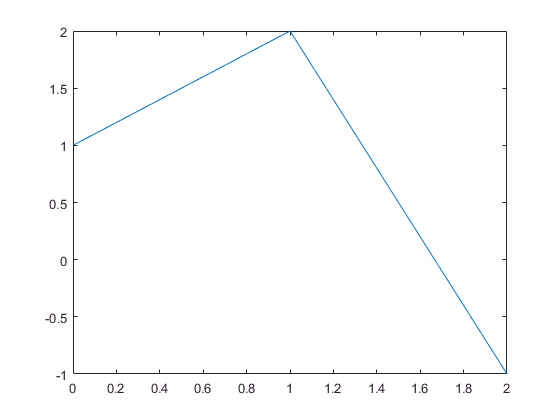

x = [0,1,2];
y = [1,2,-1];
plot(x,y)

2. Representar sólo los puntos empleando el comando `plot`

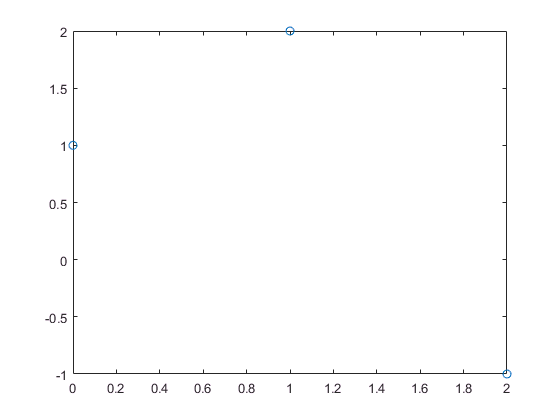

plot(x,y,'o')

3. Añadir un título a la gráfica utilizando `title `

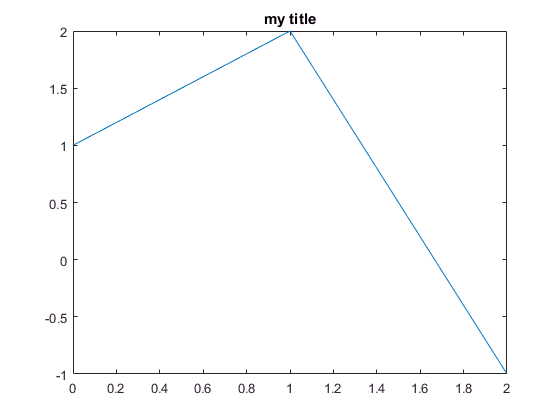

plot(x,y)
title('my title')

4. Añadir nombres a los ejes con los comando `xlabel` y `ylabel`

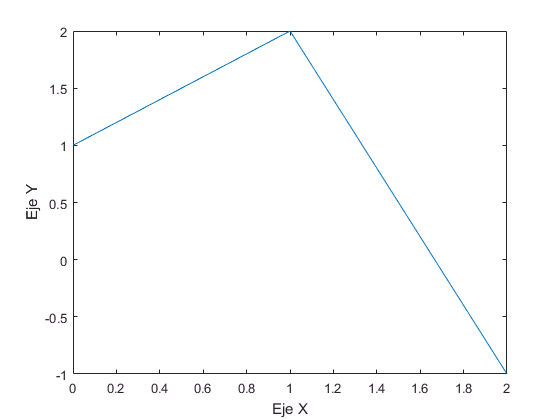

plot(x,y)
xlabel('Eje X')
ylabel('Eje Y')

## Representación directa de funciones conocidas

1. Representar la función $\sin (x)$ en el intervalor $[0,\pi]$ utilizando la función f`plot`

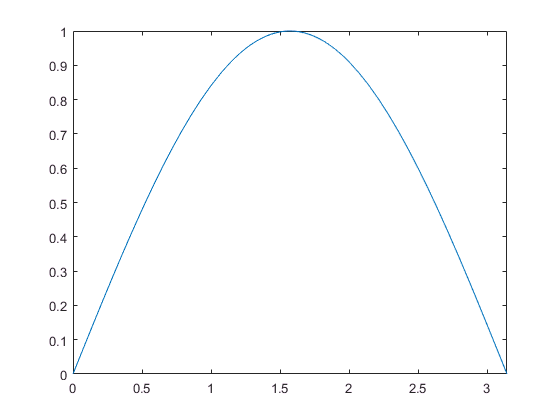

fplot(@(x) sin(x),[0 pi])

## Representación de funciones empleando escalar

1. Representar la función $\sin (x)$ en el intervalor $[0,\pi]$ utilizando la información en los puntos $x=0,0.1, \cdots, \pi$ 

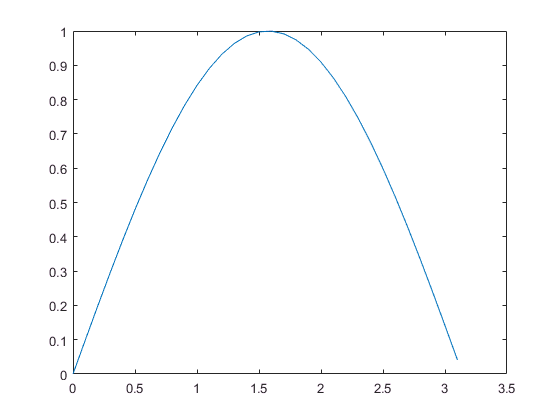

x = 0:0.1:pi;
y = sin(x);
plot(x,y)

## Representar varias gráficas en la misma figura

1. Representar, sobre los mismo ejes usando el comando `hold`, las funciones $\sin (x)$ y $\cos (x)$

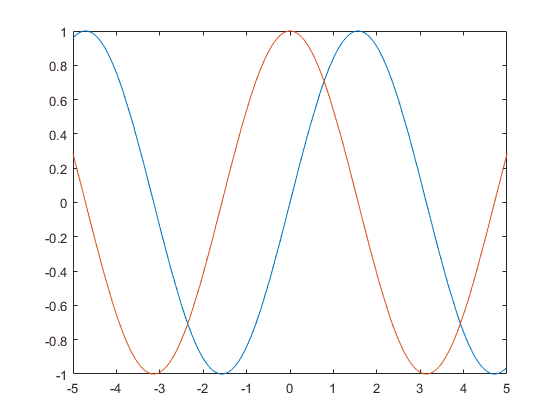

fplot(@(x) sin(x))
hold on
fplot(@(x) cos(x))

2. Representar, en la figura pero en diferentes ejes uno al lado del otro utilizando el comando `subplot`, las funciones $\sin (x)$ y $\cos (x)$, colocando sus repectivos títulos

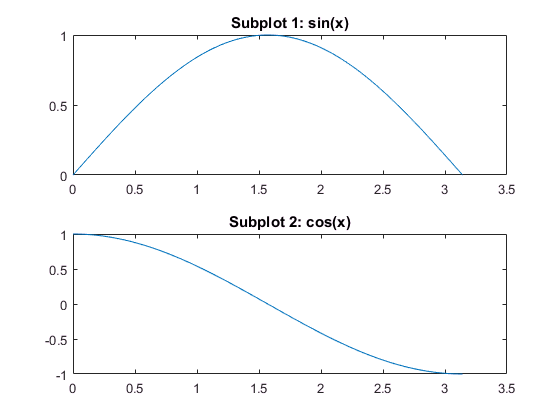

subplot(2,1,1)
x = linspace(0,pi);
y1 = sin(x);
plot(x,y1)
title('Subplot 1: sin(x)')

subplot(2,1,2)
y2 = cos(x);
plot(x,y2)
title('Subplot 2: cos(x)')

## Introduccion a la programacion 

## Condicionales

1. Dados $a=1, b= 0$ si $a < b$

a=1;
b=0;
if a<b
    disp('Sí')
else
    disp('No')
end

No


2. Comprobar si $a < b$ ó $b < -a$

if a<b
    disp('a es menor que b')
else
    disp('a es mayor que b')
end

a es mayor que b


3. Comprobar si $a > b$ y $a > 2b$

if a>b, a>2*b;
    disp('Sí')
else
    disp('No')
end

Sí


## Salidas de texto

2. Escribir un código cuya salida sea `Hola Mundo`

disp('Hola Mundo')

Hola Mundo


## Bucles de duración conocida

1. Calcular las 5 primeros elementos de la sucesión definida por recursión 


$$a_0 =1, a_1=1, a_{n}=a_{n-1} + a_{n-2}$$


a = zeros(5,1);
a(1) = 1;
a(2) = 1;
for i = 3:5
    a(i) = a(i-1) + a(i-2);
end 
disp(a)

     1
     1
     2
     3
     5



## Bucles de duración desconocida

2. Calcular los elementos de la sucesión mientras la sucesión no supere 10

a = zeros(1,5);
a(1) = 1;
a(2) = 1;
i = 3;
t = 0;
while(a(i) < 10)
    a(i) = a(i-1) + a(i-2);
    i = i + 1;
end 
disp(a)

     1     1     2     3     5     8    13

